% Given Parameters
P1 = 50;         % Pressure P1 in Pascals
P2 = 0;          % Pressure P2 in Pascals (absolute pressure)
d = 0.8e-3;      % Diameter of the capillary tube in meters
L = 0.1;         % Length of the capillary tube in meters
t2 = [6, 10, 20, 30, 40]; % Time values in seconds

% Calculate Viscosity for each t2
viscosities = (P1 * d^2) ./ (32 * L * t2);

% Convert viscosity from Pa.s to mPa.s
viscosities_mPas = viscosities * 1e3;

% Display results
fprintf('t2(s)  Viscosity (mPa.s)\n');

t2(s)  Viscosity (mPa.s)


fprintf('-------------------------\n');

-------------------------


for i = 1:length(t2)
    fprintf('%d      %.4f\n', t2(i), viscosities_mPas(i));
end

6      0.0017
10      0.0010
20      0.0005
30      0.0003
40      0.0003


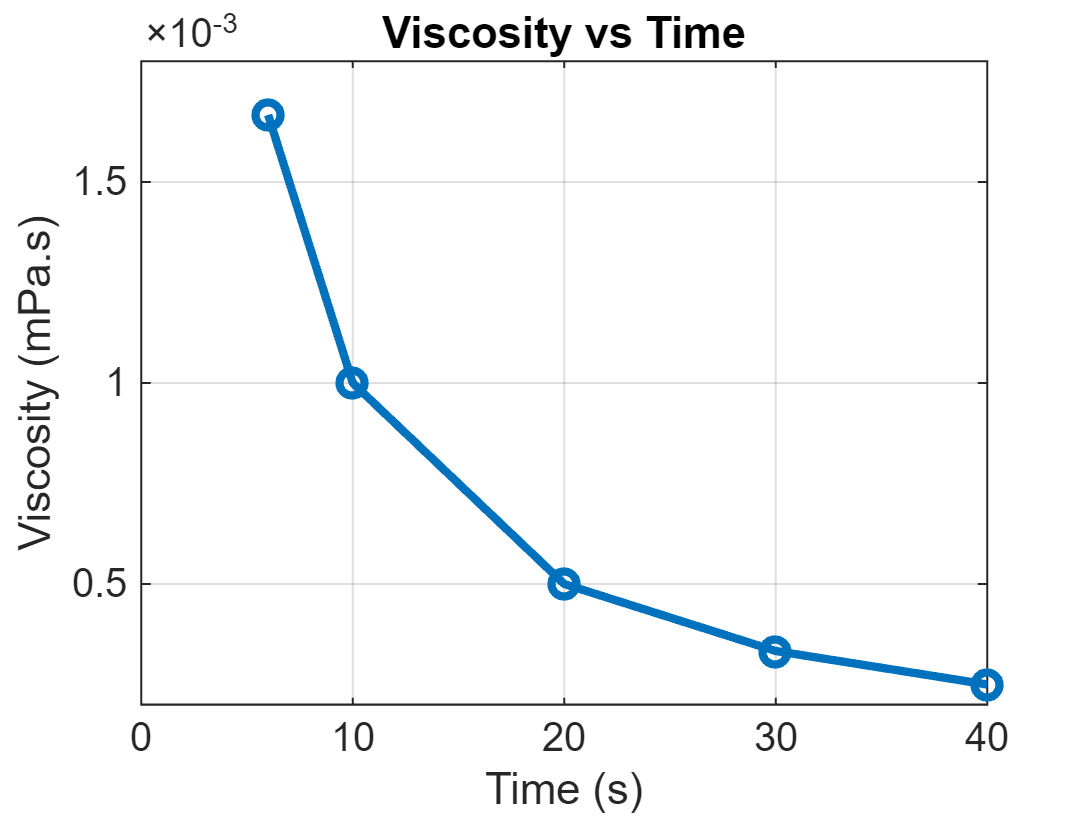


% Plotting the Viscosity vs Time
figure;
plot(t2, viscosities_mPas, '-o', 'LineWidth', 2, 'MarkerSize', 6);
title('Viscosity vs Time');
xlabel('Time (s)');
ylabel('Viscosity (mPa.s)');
grid on;